# EEG Signal Spectral Analysis

Author: Trung Van

Email: trung.van@tuni.fi

## Load data & Initialize params

### Sleep dataset

clear;
[x, Fs, Start_date, Start_time, Label, Dimension, Coef, Nmb_chans,N] = readedf_EX1('sc4002e0.rec',0,0,360);
windows = int16([128 256 512]);
overlaps = double([0 0.25 0.50 0.75]);
dft_points = [64 128 256 512 1024];

### Signal overview

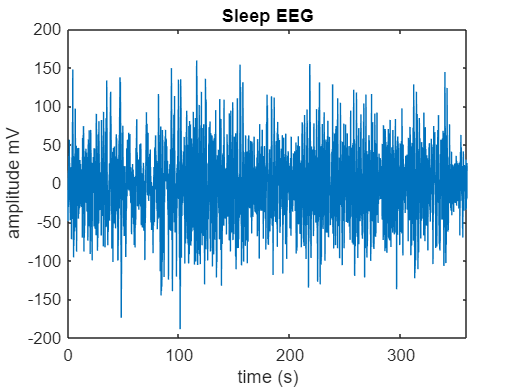

figure
time = linspace(0,length(x)/Fs, length(x));
plot(time,x)
axis('normal')
title('Sleep EEG')
xlim([0 length(time)/Fs])
xlabel('time (s)')
ylabel('amplitude mV')

## 1. PSD params experiment

### 1.1 Window size

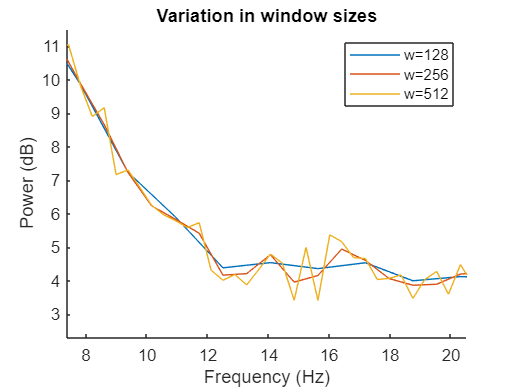

figure
hold on
for i=1:length(windows)
    [pxx, f] = pwelch(x,windows(i),overlaps(3)*windows(i),dft_points(i),100);
    plot(f, pow2db(pxx))
end
legend(sprintf('w=%d', windows(1)), ...
    sprintf('w=%d',windows(2)), ...
    sprintf('w=%d', windows(3)))
xlabel('')
title('Variation in window sizes')
xlabel('Frequency (Hz)')
ylabel('Power (dB)')
hold off
% Better visualization for comparision
xlim([7.37 20.53])
ylim([2.30 11.52])

### 1.2 Overlap

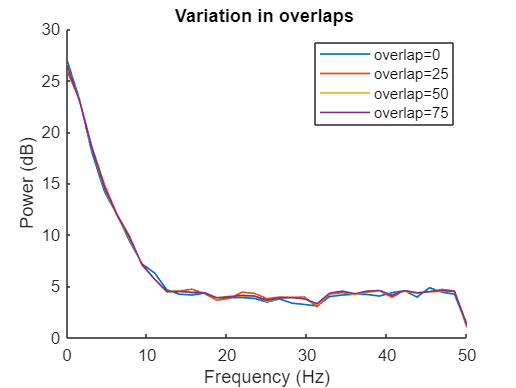

figure
hold on
noverlaps = overlaps .* 128;
for i=1:length(noverlaps)
    [pxx, f] = pwelch(x, windows(1), noverlaps(floor(i)), dft_points(1), 100);
    plot(f, pow2db(pxx),'LineWidth',1)
end
legend(sprintf('overlap=%d %', overlaps(1)*100), ...
        sprintf('overlap=%d %', overlaps(2)*100), ...
        sprintf('overlap=%d %', overlaps(3)*100),...
        sprintf('overlap=%d %', overlaps(4)*100))
xlabel('')
title('Variation in overlaps ')
xlabel('Frequency (Hz)')
ylabel('Power (dB)')
hold off

### 1.3 Number of DFT points

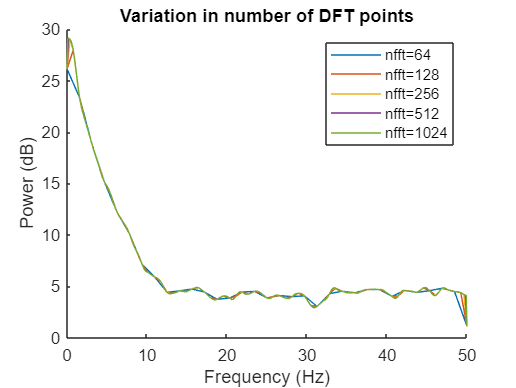

figure
hold on
for i=1:length(dft_points)
    [pxx, f] = pwelch(x,windows(1),overlaps(2)*windows(1),dft_points(i),100);
    plot(f, pow2db(pxx))
end
legend(sprintf('nfft=%d', dft_points(1)), ...
    sprintf('nfft=%d',dft_points(2)), ...
    sprintf('nfft=%d',dft_points(3)), ...
    sprintf('nfft=%d',dft_points(4)), ...
    sprintf('nfft=%d', dft_points(5)))
xlabel('')
title('Variation in number of DFT points')
xlabel('Frequency (Hz)')
ylabel('Power (dB)')
hold off

## 2. Spectrogram params experiment

spec_w_1 = 128;
spec_w_2 = 512;
spec_o_1 = 0.5;
spec_o_2 = 0.8;
spec_o_3 = 0.2;
spec_nfft_1 = 128;
spec_nfft_2 = 1024;

### 2.1 Window size

Small window size results in high detail frequecy representation.

Large window size results in blocky-looking frequecy representation.

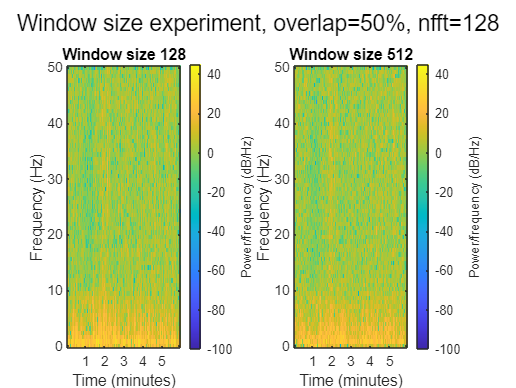

figure;
subplot(1,2,1);
spectrogram(x,spec_w_1,64,128,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('Window size %d', spec_w_1))

subplot(1,2,2);
spectrogram(x,spec_w_2, spec_o_1 * spec_w_2,128,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('Window size %d', spec_w_2))

sgtitle(sprintf('Window size experiment, overlap=%d%%, nfft=%d', spec_o_1*100, spec_nfft_1));

### 2.2 Overlap

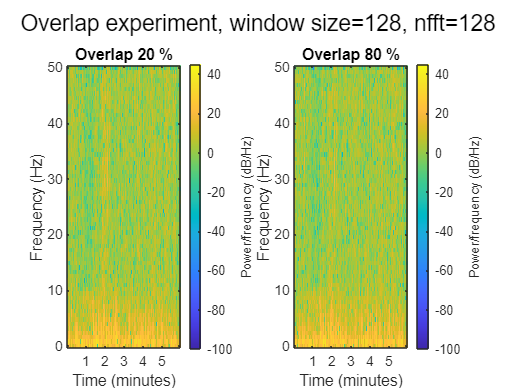

figure;
subplot(1,2,1);
spectrogram(x,spec_w_1,int16(spec_w_1 * spec_o_3),128,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('Overlap %d %%', spec_o_3 * 100))

subplot(1,2,2);
spectrogram(x,spec_w_1,int16(spec_w_1 * spec_o_2),128,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('Overlap %d %%', spec_o_2 * 100))

sgtitle(sprintf('Overlap experiment, window size=%d, nfft=%d', spec_w_1, spec_nfft_1));

### 2.3 Number of DFT points

Higher nfft gives smoother spectrogram

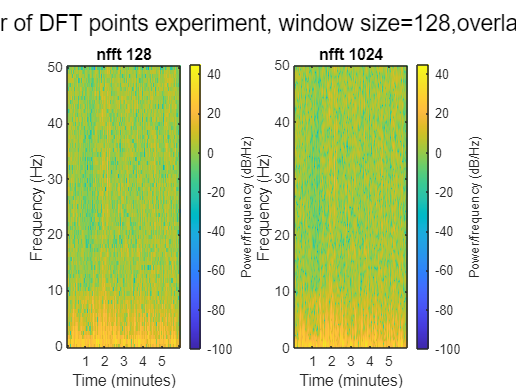

figure;
subplot(1,2,1);
spectrogram(x,spec_w_1,int16(spec_w_1 * spec_o_1),spec_nfft_1,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('nfft %d', spec_nfft_1))

subplot(1,2,2);
spectrogram(x,spec_w_1,int16(spec_w_1 * spec_o_1),spec_nfft_2,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('nfft %d', spec_nfft_2))
sgtitle(sprintf('Number of DFT points experiment, window size=%d,overlap=%d%%', spec_w_1, spec_o_1*100));

## 3. Self measured data

Repeat the assesment with self-measured data from EEG lab session

clear;
load('EEG_lab0.mat');
x = data(:,1);
Fs = 1000 / isi;

windows = int16([256 512 1024]);
overlaps = [0, 0.25, 0.50, 0.75];
dft_points = int16([256 512 1024]);

### 3.1 Signal overview

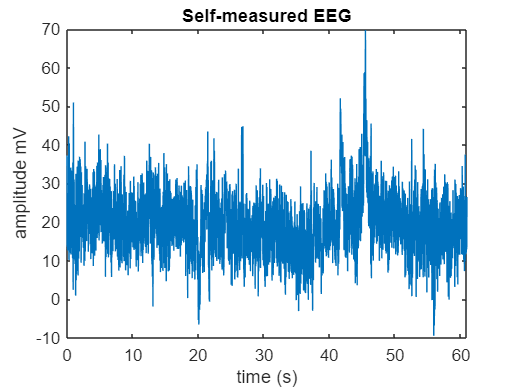

figure
time = linspace(0,length(x)/Fs, length(x));
plot(time,x)
axis('normal')
title('Self-measured EEG')
xlim([0 length(time)/Fs])
xlabel('time (s)')
ylabel('amplitude mV')

### 3.2 PSD param experiments

Parameter initialize

overlap_1 = 0.5;
overlap_2 = 0.75;
overlap_3 = 0.25;
window_1 = 512;
window_2 = 128;
nfft_1 = 256;
nfft_2 = 512;

#### 3.2.1 Window size

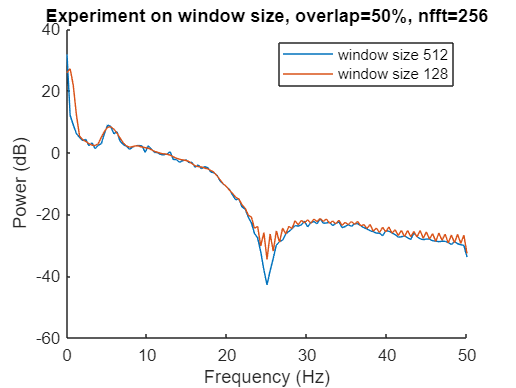

figure
hold on
title(sprintf('Experiment on window size, overlap=%d%%, nfft=%d', overlap_1*100, nfft_1));
[pxx_temp, f] = pwelch(x,window_1, window_1 * overlap_1, nfft_1,100);
plot(f, pow2db(pxx_temp));
[pxx_temp, f] = pwelch(x,window_2, window_2 * overlap_1, nfft_1,100);
plot(f, pow2db(pxx_temp));
xlabel('Frequency (Hz)')
ylabel('Power (dB)')
legend(sprintf('window size %d %', window_1), ...
        sprintf('window size %d %', window_2))
hold off

#### 3.2.2 Overlap

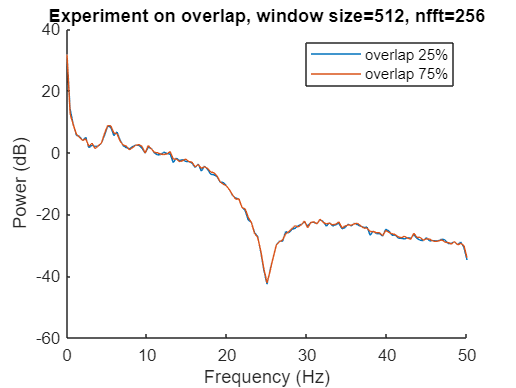

figure
hold on
title(sprintf('Experiment on overlap, window size=%d, nfft=%d', window_1, nfft_1));
[pxx_temp, f] = pwelch(x,window_1, window_1 * overlap_3, nfft_1,100);
plot(f, pow2db(pxx_temp));
[pxx_temp, f] = pwelch(x,window_1, window_1 * overlap_2, nfft_1,100);
plot(f, pow2db(pxx_temp));
xlabel('Frequency (Hz)')
ylabel('Power (dB)')
legend(sprintf('overlap %d%%', overlap_3*100), ...
        sprintf('overlap %d%%', overlap_2*100))
hold off

#### 3.2.3 Number of DFT points

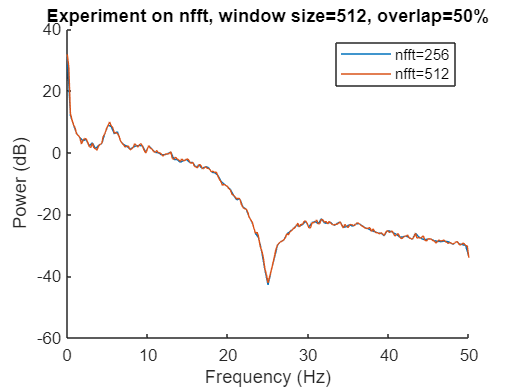

figure
hold on
title(sprintf('Experiment on nfft, window size=%d, overlap=%d%%', window_1, overlap_1*100));
[pxx_temp, f] = pwelch(x,window_1, window_1 * overlap_1, nfft_1,100);
plot(f, pow2db(pxx_temp));
[pxx_temp, f] = pwelch(x,window_1, window_1 * overlap_2, nfft_2,100);
plot(f, pow2db(pxx_temp));
xlabel('Frequency (Hz)')
ylabel('Power (dB)')
legend(sprintf('nfft=%d', nfft_1), ...
        sprintf('nfft=%d', nfft_2))
hold off

### 3.3 Spectrogram param experiment

In this experiment, we use the same variation as with the sleep EEG.

spec_w_1 = 128;
spec_w_2 = 512;
spec_o_1 = 0.5;
spec_o_2 = 0.8;
spec_o_3 = 0.2;
spec_nfft_1 = 128;
spec_nfft_2 = 1024;

#### 3.3.1 Window size

Small window size results in high detail frequecy representation.

Large window size results in blocky-looking frequecy representation.

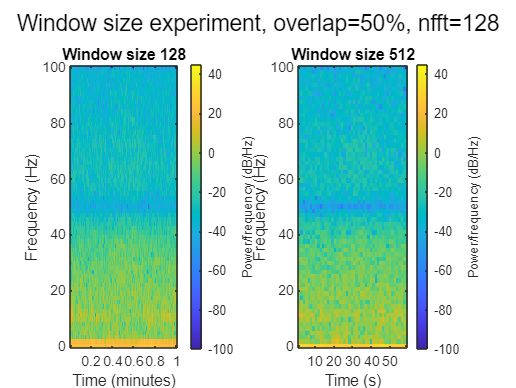

figure;
subplot(1,2,1);
spectrogram(x,spec_w_1,spec_o_1*spec_w_1,128,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('Window size %d', spec_w_1))

subplot(1,2,2);
spectrogram(x,spec_w_2,spec_o_1*spec_w_2,128,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('Window size %d', spec_w_2))
sgtitle(sprintf('Window size experiment, overlap=%d%%, nfft=%d', spec_o_1*100, spec_nfft_1));

#### 3.3.2 Overlap

Higher overlap results in smoother spectrogram.

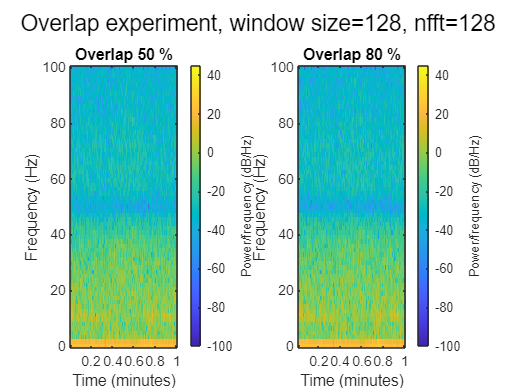

figure;
subplot(1,2,1);
spectrogram(x,spec_w_1,int16(spec_w_1 * spec_o_1),128,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('Overlap %d %%', spec_o_1 * 100))

subplot(1,2,2);
spectrogram(x,spec_w_1,int16(spec_w_1 * spec_o_2),128,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('Overlap %d %%', spec_o_2 * 100))

sgtitle(sprintf('Overlap experiment, window size=%d, nfft=%d', spec_w_1, spec_nfft_1));

#### 3.3.3 Number of DFT points

Higher nfft gives smoother spectrogram

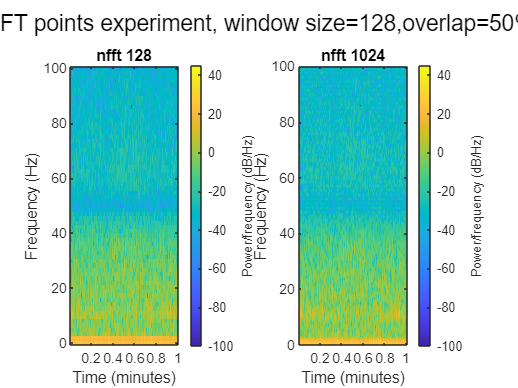

figure;
subplot(1,2,1);
spectrogram(x,spec_w_1,int16(spec_w_1 * spec_o_1),spec_nfft_1,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('nfft %d', spec_nfft_1))

subplot(1,2,2);
spectrogram(x,spec_w_1,int16(spec_w_1 * spec_o_1),spec_nfft_2,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('nfft %d', spec_nfft_2))
sgtitle(sprintf('DFT points experiment, window size=%d,overlap=%d%%', spec_w_1, spec_o_1*100));

### Save figures

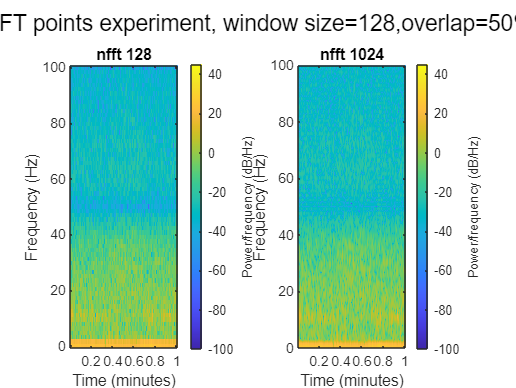

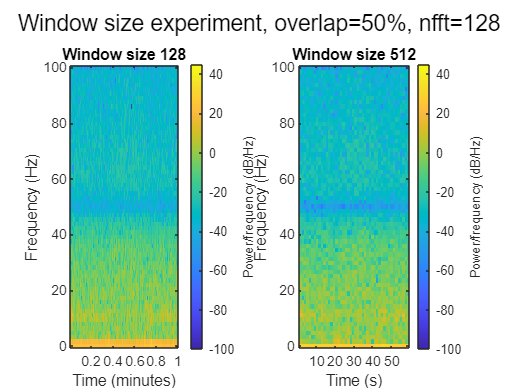

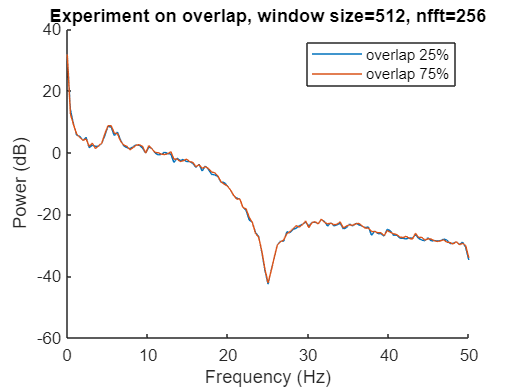

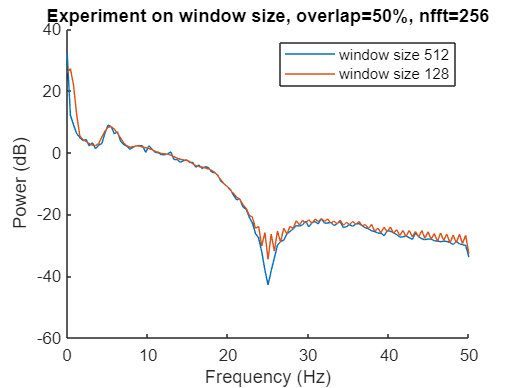

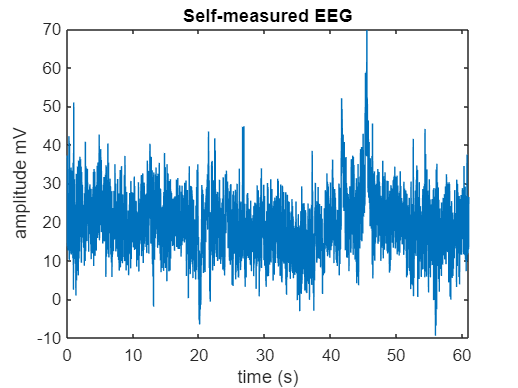

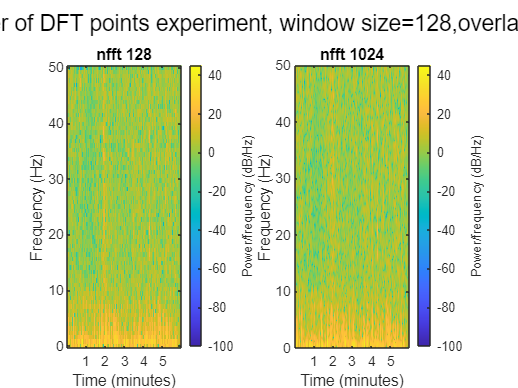

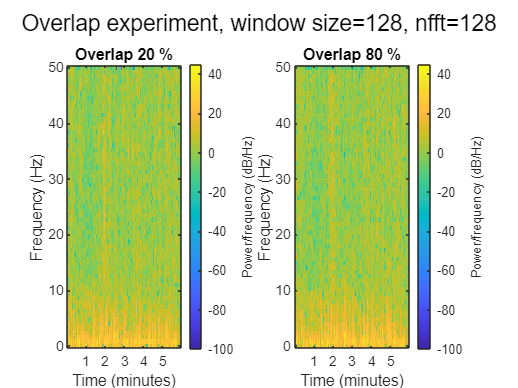

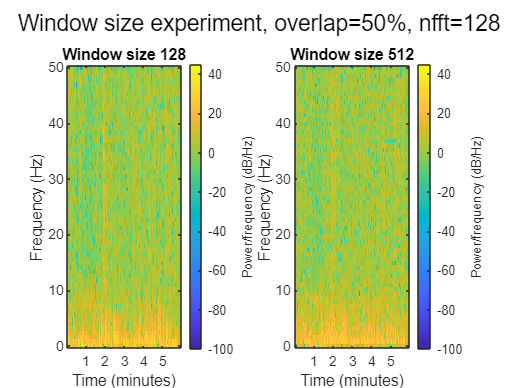

FolderName = 'P:\StudentDocuments\Documents\MATLAB\BiomedicalSignalAnalysis\assignment2\figure';
FigList = findobj(allchild(0), 'flat', 'Type', 'figure');
for iFig = 1:length(FigList)
  FigHandle = FigList(iFig);
  FigName   = num2str(get(FigHandle, 'Number'));
  set(0, 'CurrentFigure', FigHandle);
  saveas(gcf, fullfile(FolderName, [FigName '.png']));
end

### High resolution EEG spectrogram

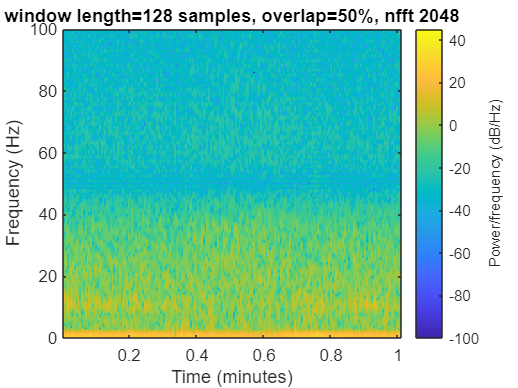

spec_nfft_3 = 2048;
figure;
spectrogram(x,spec_w_1,int16(spec_w_1 * spec_o_1),spec_nfft_3,Fs,'yaxis');
set(gca, 'Clim', [-100 45]);
title(sprintf('window length=%d samples, overlap=%d%%, nfft %d',spec_w_1, spec_o_1*100 ,spec_nfft_3))